clear;
clc;
freq    = 435e6;
lambda  = 3e8/freq;
%Large Tape Measure
% offset  = lambda/50;
% spacing = lambda/2;
% %length  = lambda/2.1; %Starting estimate
% %length = 0.3235;
% length = 0.32756501182;
% %width   = lambda/50;
% width = 25e-3;
% anglevar= 0:10:180;
% freqrange = 333e6:1e6:533e6;
% gndspacing = 0.005;

%Small tape measure
offset  = lambda/50;
spacing = lambda/2;
% length  = lambda/2.1; %Starting estimate
length = 0.3371;
width = 12.3e-3;
anglevar= 0:10:180;
freqrange = 333e6:1e6:533e6;
gndspacing = 0.005;

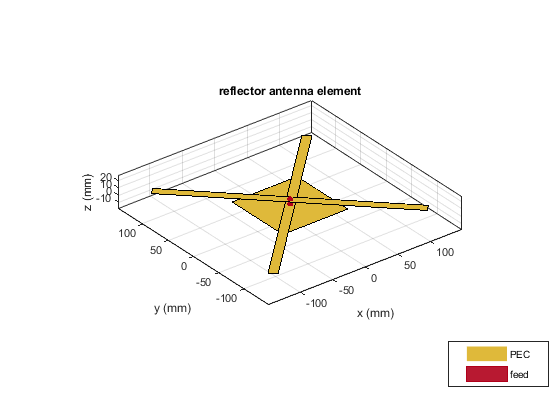


% steel = metal('Steel')
% copper = metal('Copper')

steel_dc_r = 0.1750777; %ohms
copper_dc_r = 0.0042595; %ohms

copper_le = lumpedElement("Impedance", copper_dc_r);
steel_le = lumpedElement("Impedance", steel_dc_r);

d  = dipole('Length',length,'Width',width, "Load", copper_le); % "Conductor", coppr);

d_steel = dipole('Length',length,'Width', width, "Load", steel_le); % "Conductor", steel);

ant = dipoleCrossed('Element',d_steel,'Tilt',90,'TiltAxis',[0 1 0], 'FeedPhase',[90 0]);
% show(ant);
ant_gnd = reflector('Exciter',ant,'GroundPlaneLength',0.1,              ...
     'GroundPlaneWidth', 0.1,'Spacing',gndspacing);
show(ant_gnd)

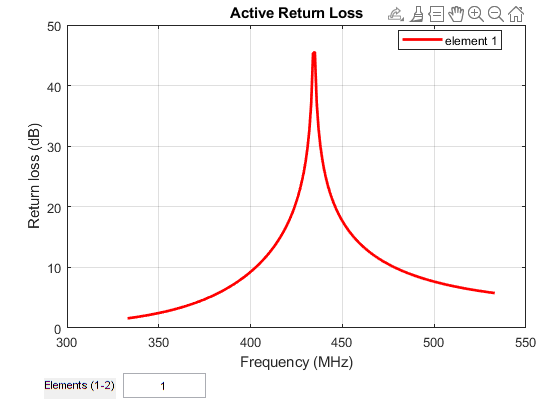

figure;
returnLoss(ant_gnd, freqrange, 75);

[M,I] = max(returnLoss(ant_gnd, freqrange, 75));

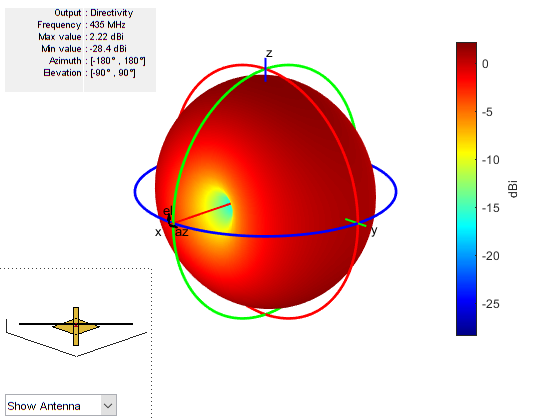

figure;
pattern(ant_gnd, freq);

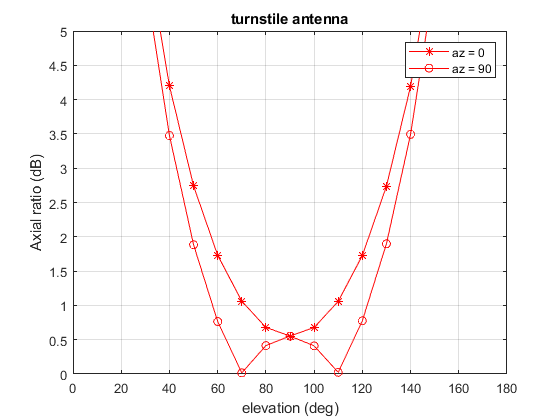


ar1 = axialRatio(ant, freq, 0, anglevar);
ar2 = axialRatio(ant, freq, 90, anglevar);

ar1_gnd = axialRatio(ant, freq, 0, anglevar);
ar2_gnd = axialRatio(ant, freq, 90, anglevar);

figure;
plot(anglevar, ar1_gnd, 'r*-', anglevar, ar2_gnd, 'ro-');
axis([0 180 0 5]);
grid on;
xlabel('elevation (deg)');
legend('az = 0', 'az = 90')
ylabel('Axial ratio (dB)');
title('turnstile antenna');

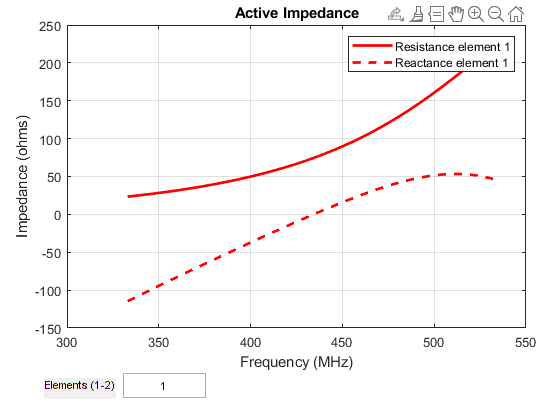

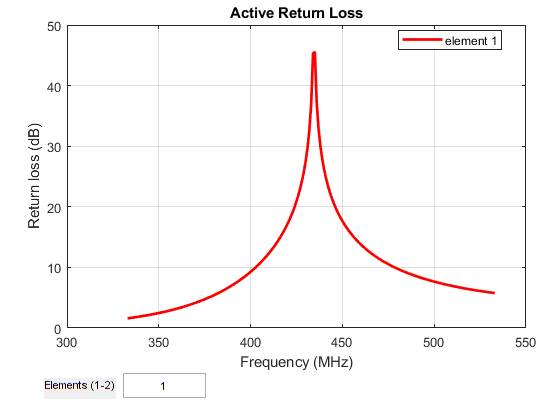

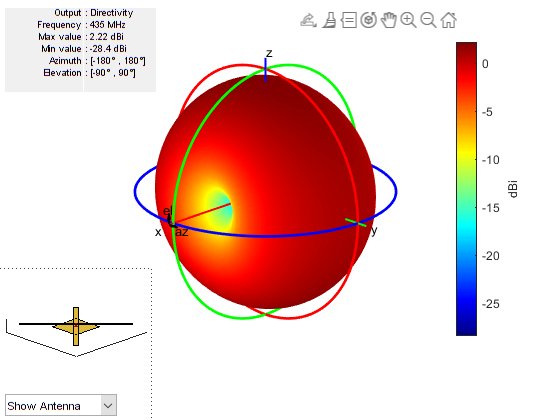

figure;
impedance(ant_gnd, freqrange);

match = matchingnetwork("CenterFrequency", freq, "Bandwidth", 3e6, "SourceImpedance", 50, "LoadImpedance", 75);

[circuit_list, performance] = circuitDescriptions(match)

circuit_list = 2×5 table
                 circuitName    component1Type    component1Value    component2Type    component2Value
                 ___________    ______________    _______________    ______________    _______________

    Circuit 1     "auto_1"        "Series L"        1.2936e-08         "Shunt C"         3.4495e-12   
    Circuit 2     "auto_2"        "Series C"        1.0348e-11         "Shunt L"         3.8807e-08   


performance = 2×4 table
                 circuitName    evaluationPassed    testsFailed     performanceScore
                 ___________    ________________    ____________    ________________

    Circuit 1     "auto_1"         {["Yes"]}        {0×0 double}       {[3.0000]}   
    Circuit 2     "auto_2"         {["Yes"]}        {0×0 double}       {[3.0000]}   


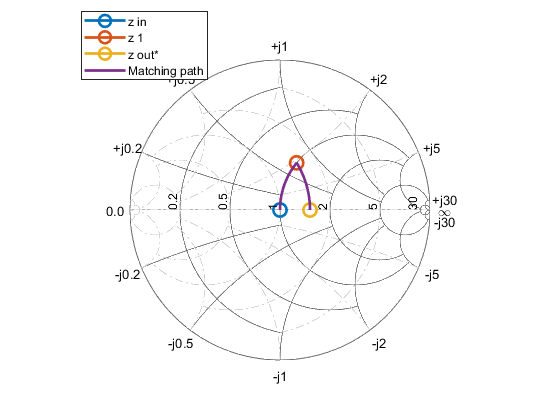

figure;
smithplot(match)

d = 0.001;
% for length = 0.3321:d:0.35;
%     d_steel = dipole('Length',length,'Width', width, "Load", steel_le); % "Conductor", steel);
%     ant= dipoleCrossed('Element',d_steel,'Tilt',90,'TiltAxis',[0 1 0], 'FeedPhase',[90 0]);
%     ant_gnd = reflector('Exciter',ant,'GroundPlaneLength',0.1,              ...
%      'GroundPlaneWidth', 0.1,'Spacing',gndspacing);
%     [M,I] = max(returnLoss(ant_gnd, freqrange, 75));
%     if freqrange(I(1)) < 435E6
%         length = length - d
%         break;
%     end
% end